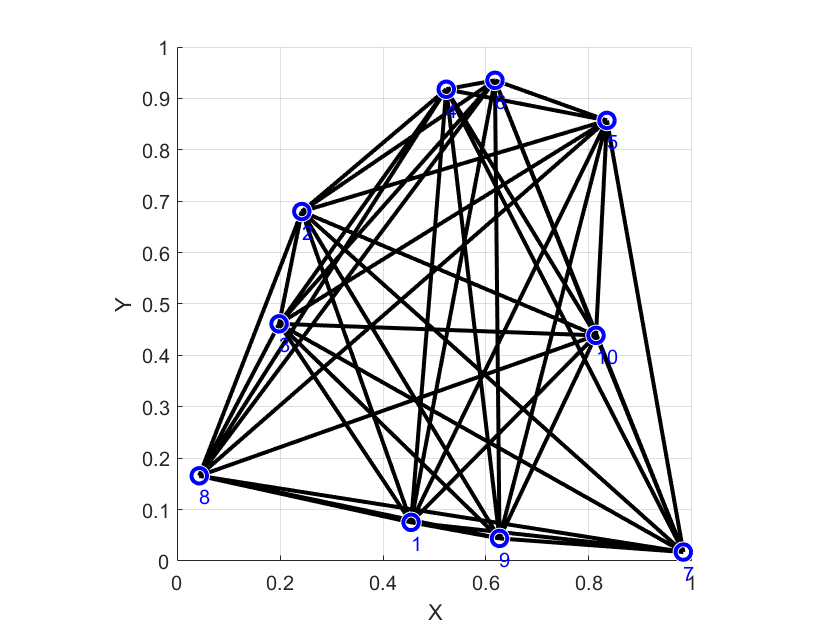

clear all
clc
close all

load('dataForLearning.mat') 
graph.drawGraph(1);

graph.loadNeighbors();

## Drawing box plots

#### Generating data for box plots

% Agent 1, RHCP2
agentId = 1;
RHCPId = 2;
numOfTargets = length(graph.targets);

collectedDataMatrix = cell(numOfTargets,numOfTargets);
dataCountMatrix = zeros(numOfTargets,numOfTargets);
for dataBlock = graph.agents(agentId).pastData
    dataBlock = cell2mat(dataBlock);
    if (RHCPId==2 & size(dataBlock,2)==3) | (RHCPId==1 & size(dataBlock,2)==4)
        i = dataBlock(1,1);
        jStar = dataBlock(1,size(dataBlock,2));
        if isempty(collectedDataMatrix{i,jStar})
            collectedData = cell(1,numOfTargets);
        else
            collectedData = collectedDataMatrix{i,jStar};
        end
        
        for jId = 1:1:size(dataBlock,1)
            j = dataBlock(jId,1);
            Omega_j = dataBlock(jId,2);
            collectedData{j} = [collectedData{j}, Omega_j];    
        end
        collectedDataMatrix{i,jStar} = collectedData;
        dataCountMatrix(i,jStar) = dataCountMatrix(i,jStar) + 1; 
    end
end
dataCountMatrix

dataCountMatrix =      0     0     0     0     0     0     0     5    15     0
     0     0     6     6     0     0     0     0     0     0
     0     8     0     0     0     0     0    11     0     0
     0     4     0     0     9     8     0     0     0     0
     0     0     0     5     0    15     0     0     0     5
     0     0     0    10    13     0     0     0     0     0
     0     0     0     0     0     0     0     0    11     0
     3     0    13     0     0     0     0     0     0     0
    17     0     0     0     0     0    11     0     0     2
     0     0     0     0     3     0     0     0     4     0


#### Drawing

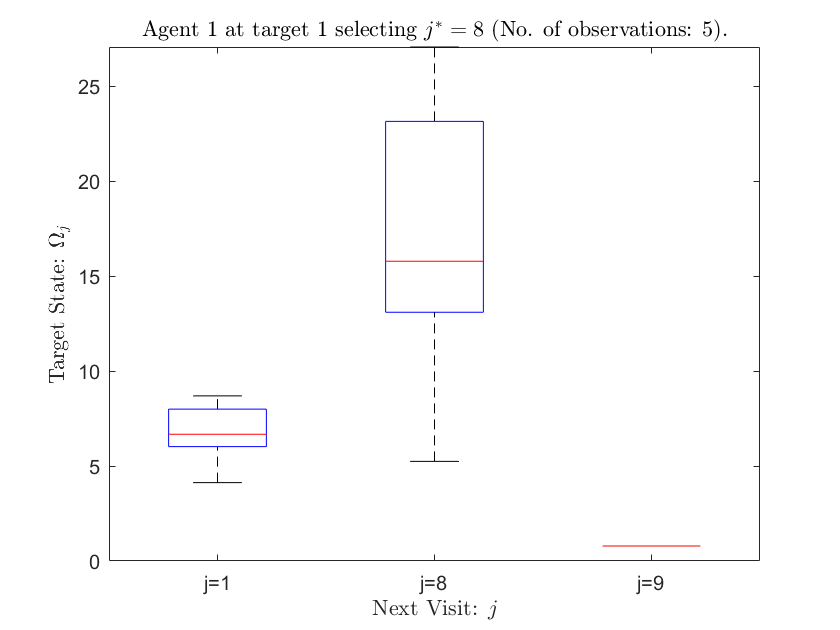

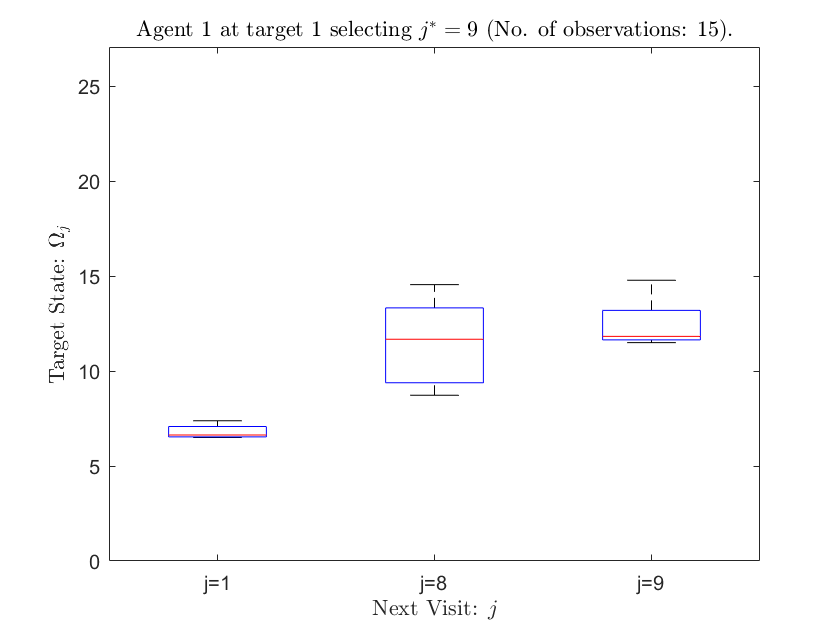

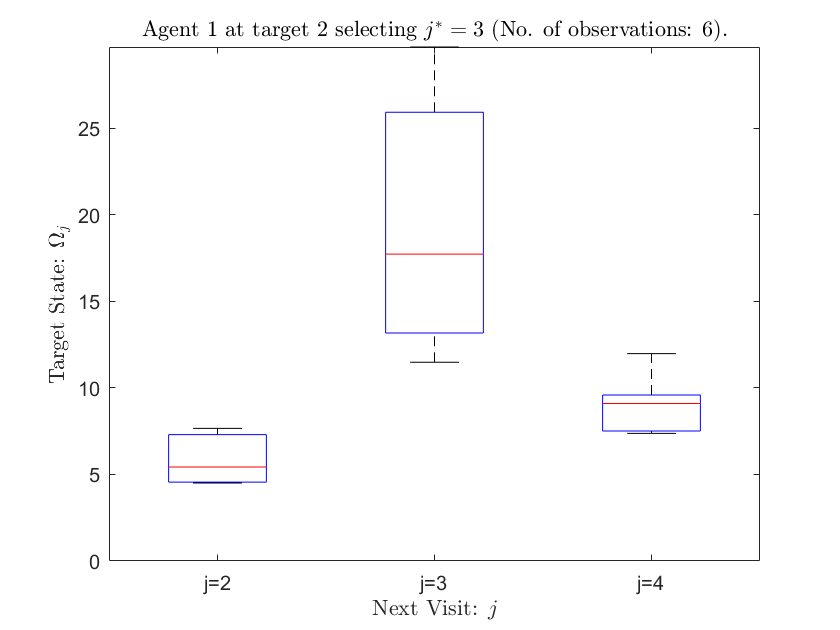

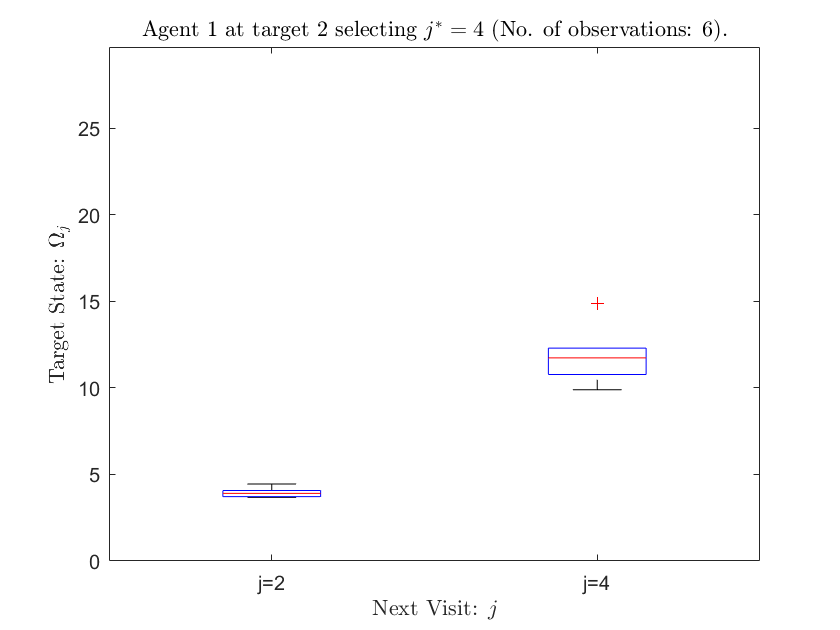

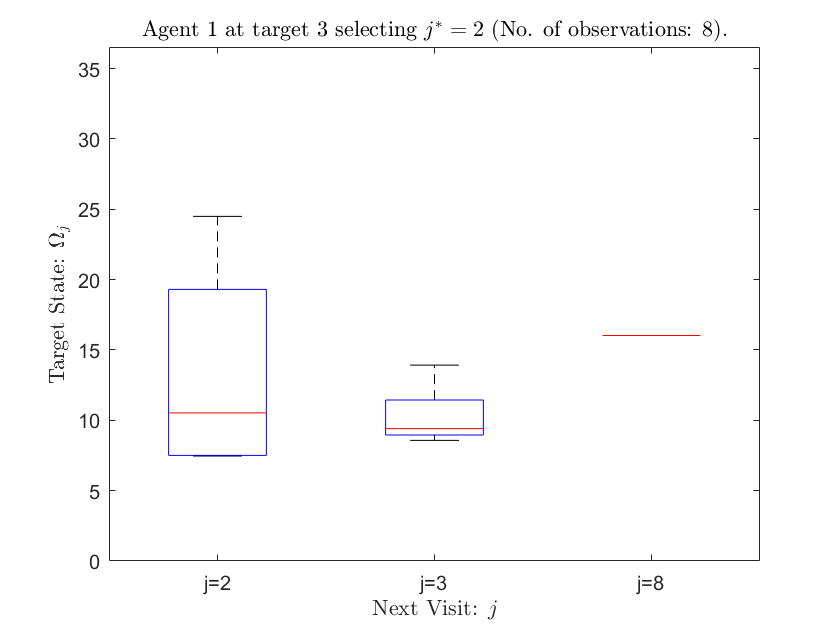

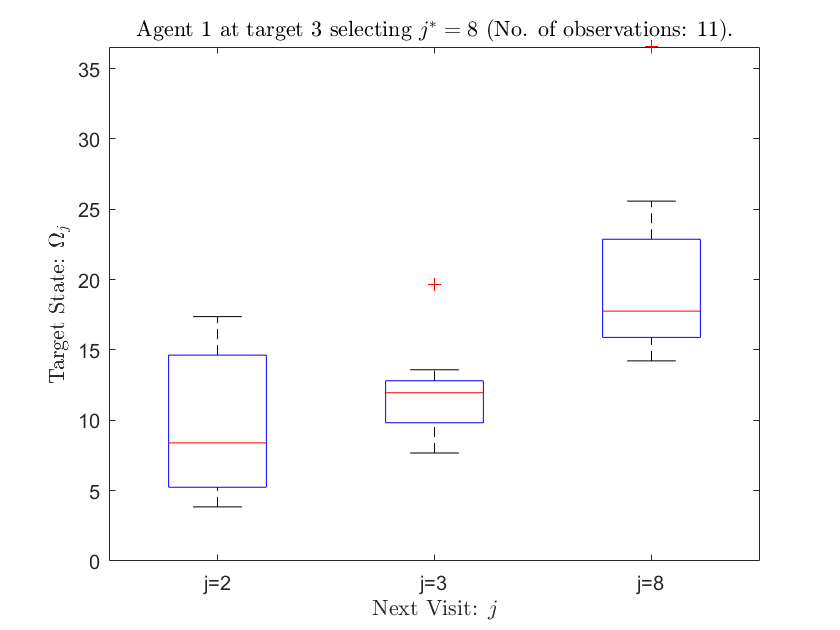

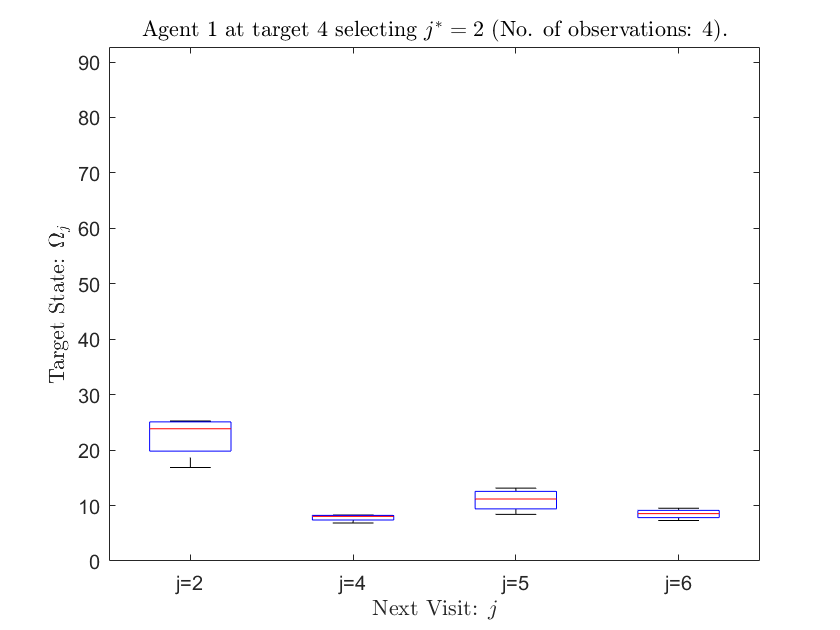

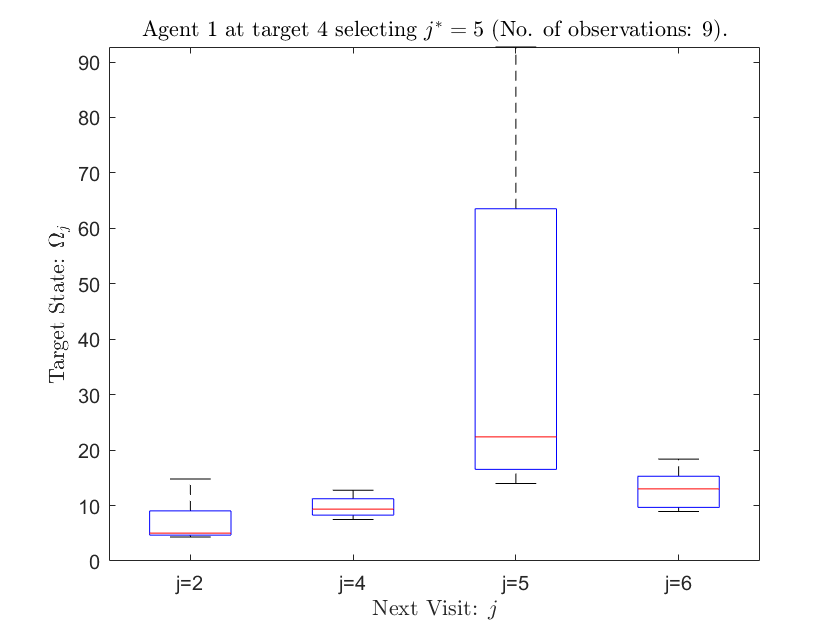

for i = 1:1:numOfTargets
    figs = [];
    maxOmega_j = 0;
    for jStar = 1:1:numOfTargets
        if dataCountMatrix(i,jStar)>0 & i~=jStar
            collectedData = collectedDataMatrix{i,jStar};
            data = [];
            dataCenters = [];
            for j = 1:1:numOfTargets
                L = length(collectedData{j}); 
                if L > 0
                    data = [data; transpose(collectedData{j})];
                    newLabels = repmat({['j=',num2str(j)]}, L, 1);
                    dataCenters = [dataCenters; newLabels];  
                end
            end
            figure
            boxplot(data,dataCenters)
            title(['Agent ',num2str(agentId),' at target ',num2str(i),' selecting $j^*=',...
                num2str(jStar),'$ (No. of observations: ',num2str(dataCountMatrix(i,jStar)),').'],"Interpreter","latex");
            xlabel('Next Visit: $j$',"Interpreter","latex");
            ylabel('Target State: $\Omega_j$',"Interpreter","latex");
            
            fig = gcf;
            figs = [figs, fig.Number];
            maxData = max(data);
            if maxData > maxOmega_j
                maxOmega_j = maxData;
            end
            
        end  
    end
    
    for fig = figs
        figure(fig);
        ylim([0,maxOmega_j]);
    end
    
end

### Generating input output data for Neural Networks

agentId = 1;
RHCPId = 2;
numOfTargets = length(graph.targets);

collectedInputMatrix = cell(1,numOfTargets);
collectedOutputMatrix = cell(1,numOfTargets);
dataCountMatrix = zeros(numOfTargets,numOfTargets);

for dataBlock = graph.agents(agentId).pastData
    dataBlock = cell2mat(dataBlock);
    if (RHCPId==2 & size(dataBlock,2)==3) | (RHCPId==1 & size(dataBlock,2)==4)
        i = dataBlock(1,1); % current target
        
        % output
        jStar = dataBlock(1,size(dataBlock,2));
        neighborIndex = find(graph.neighbors{i}==jStar)-1;
        output = zeros(length(graph.neighbors{i})-1,1);
        output(neighborIndex) = 1;
        collectedOutputMatrix{i} = [collectedOutputMatrix{i}, output];
        
        % input
        input = zeros(length(graph.neighbors{i}),1);
        for jId = 1:1:size(dataBlock,1)
            j = dataBlock(jId,1);
            neighborIndex = find(graph.neighbors{i}==j);
            
            Omega_j = dataBlock(jId,2);
            input(neighborIndex) = Omega_j;
        end
        collectedInputMatrix{i} = [collectedInputMatrix{i}, input];
        
        
        dataCountMatrix(i,jStar) = dataCountMatrix(i,jStar) + 1; 
    end
end
dataCountMatrix

dataCountMatrix =      0     0     0     0     0     0     0     5    15     0
     0     0     6     6     0     0     0     0     0     0
     0     8     0     0     0     0     0    11     0     0
     0     4     0     0     9     8     0     0     0     0
     0     0     0     5     0    15     0     0     0     5
     0     0     0    10    13     0     0     0     0     0
     0     0     0     0     0     0     0     0    11     0
     3     0    13     0     0     0     0     0     0     0
    17     0     0     0     0     0    11     0     0     2
     0     0     0     0     3     0     0     0     4     0


Learning for each target

i = 1

cases = 20

performance = 4.7179e-07

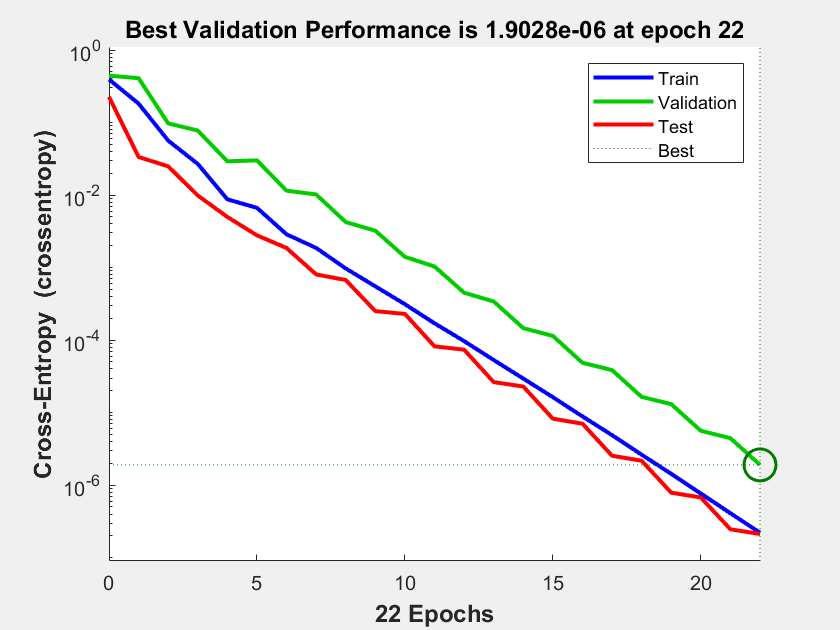

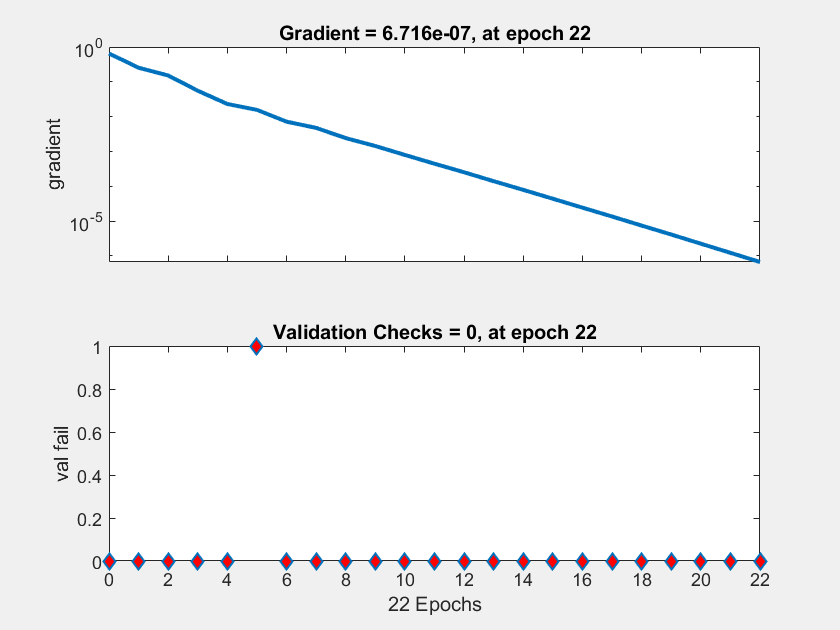

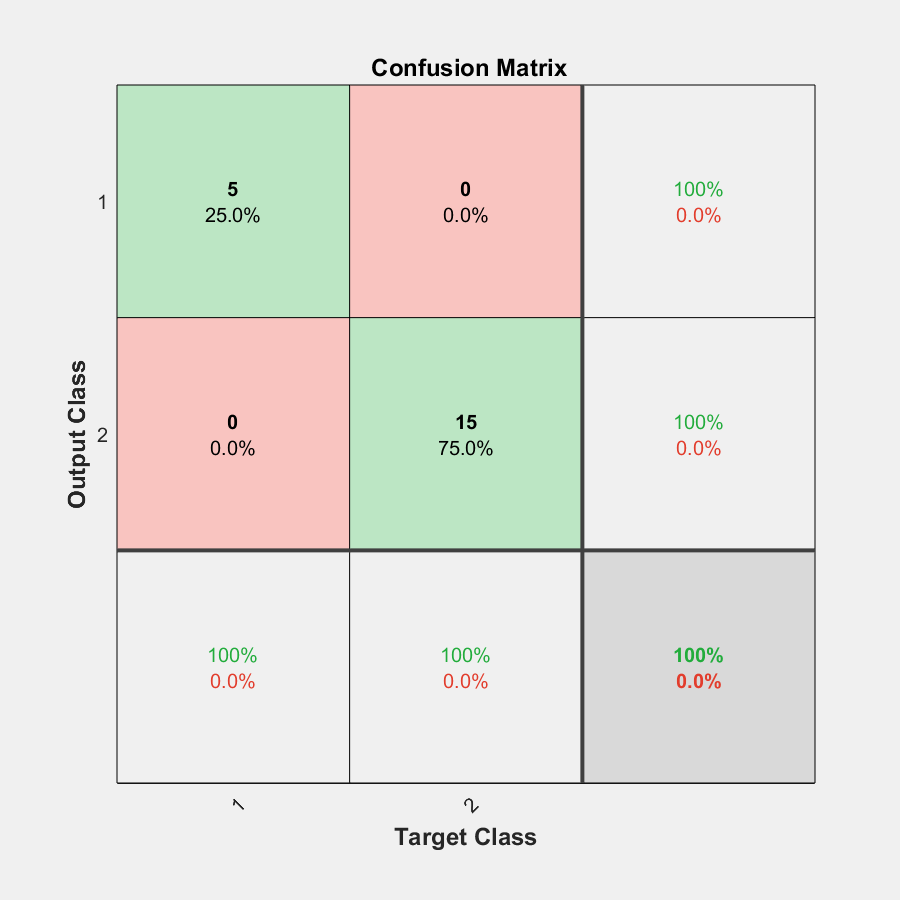

i = 2

cases = 12

performance = 5.3228e-07

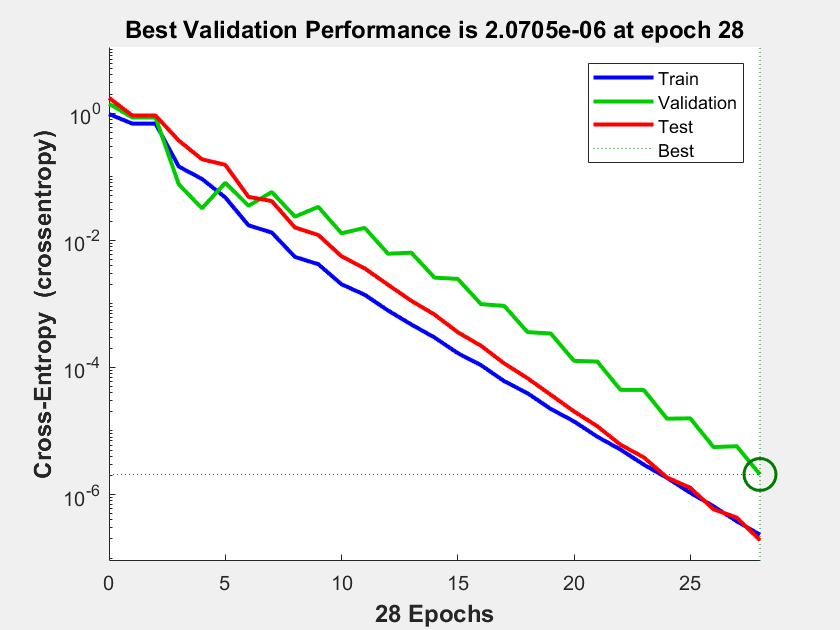

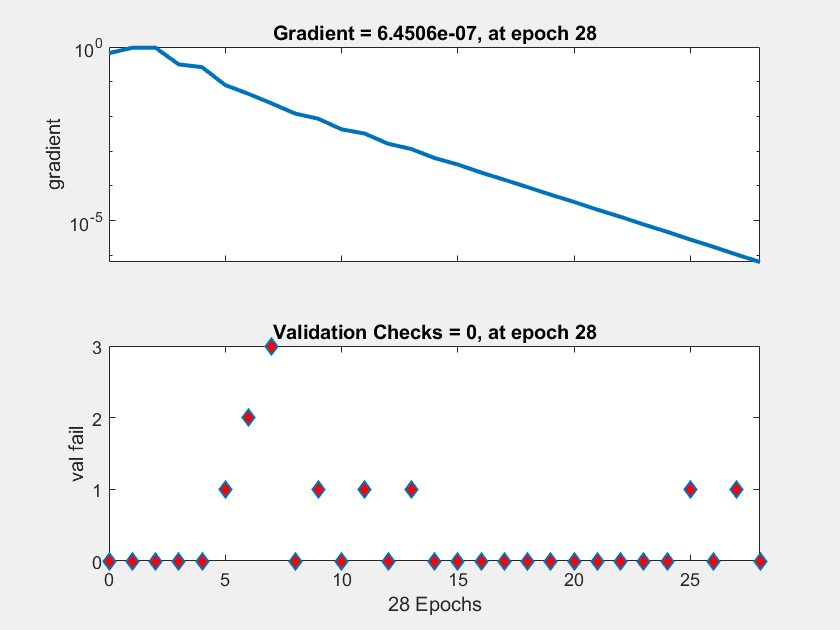

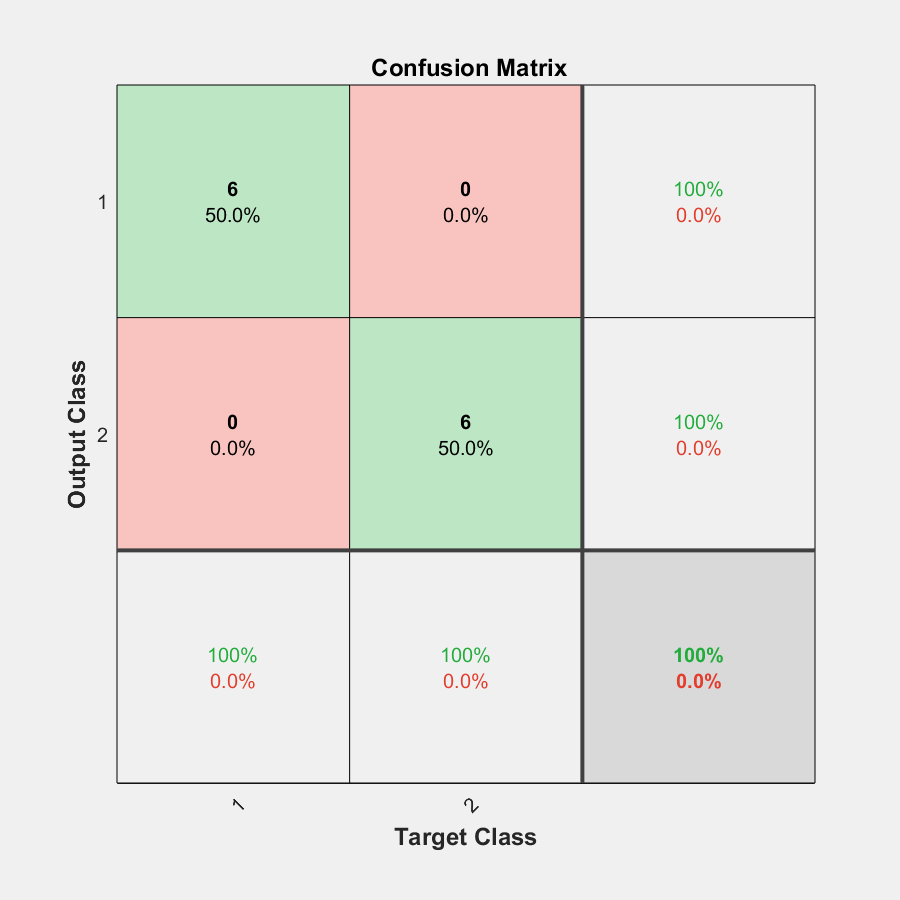

i = 3

cases = 19

performance = 0.2178

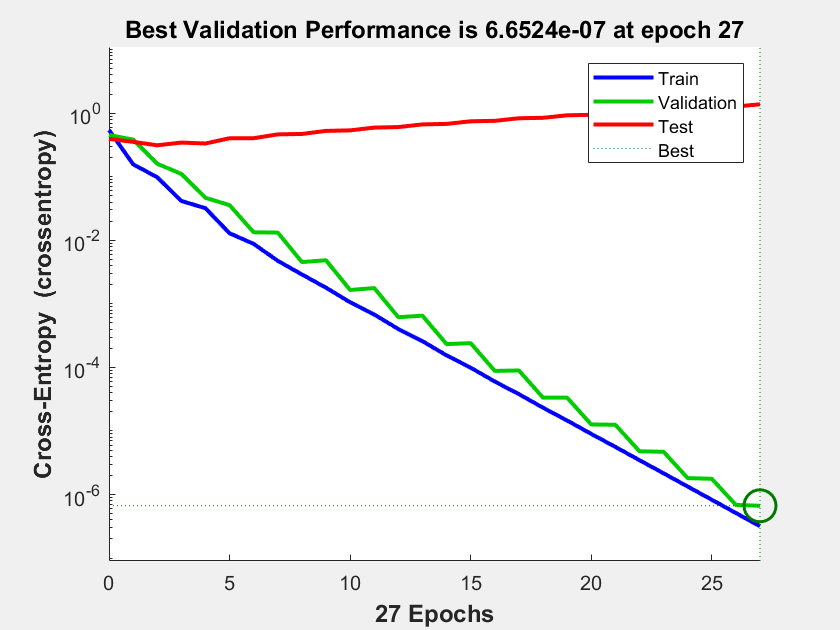

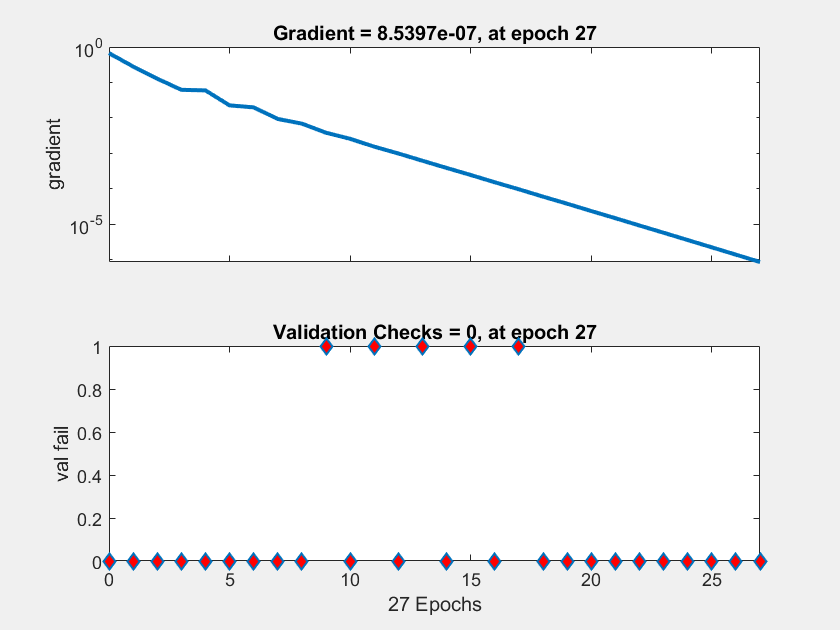

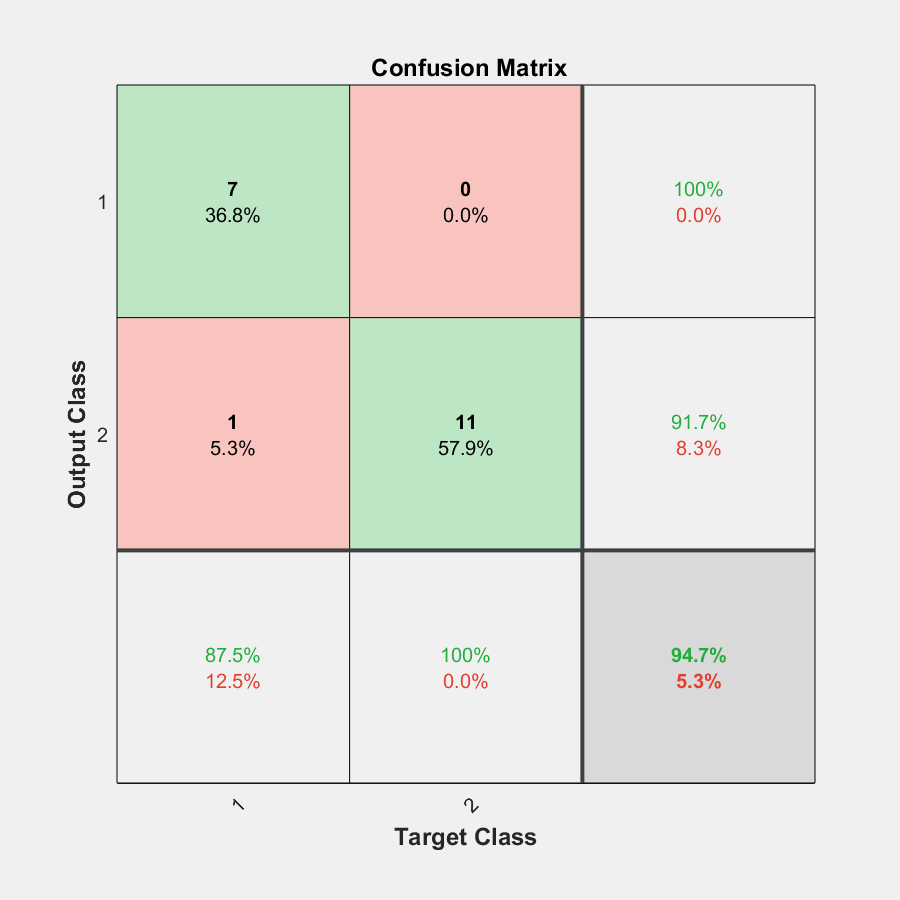

i = 4

cases = 21

performance = 0.0597

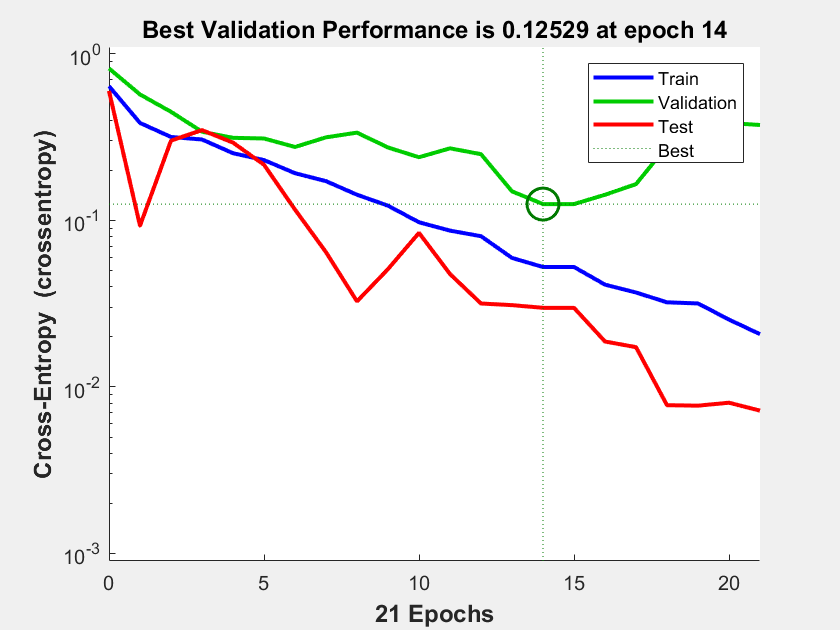

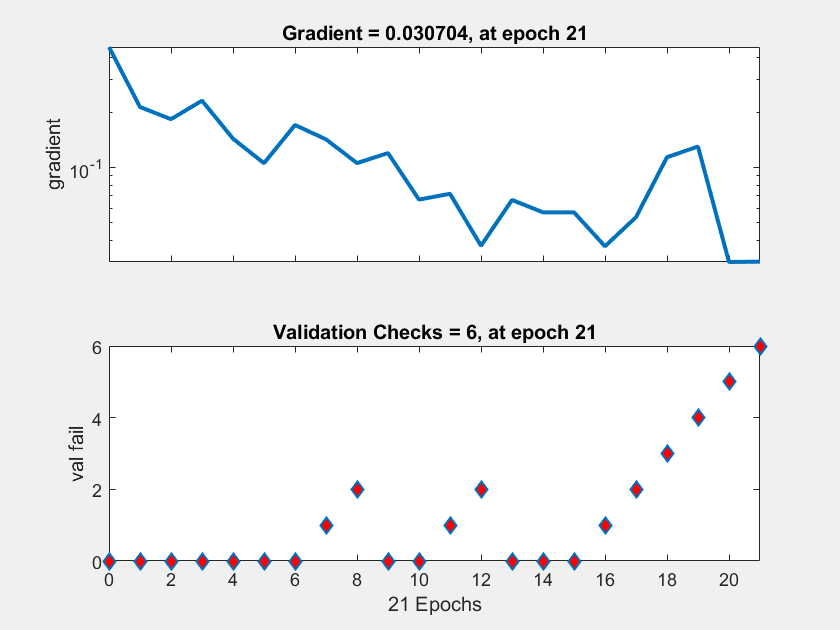

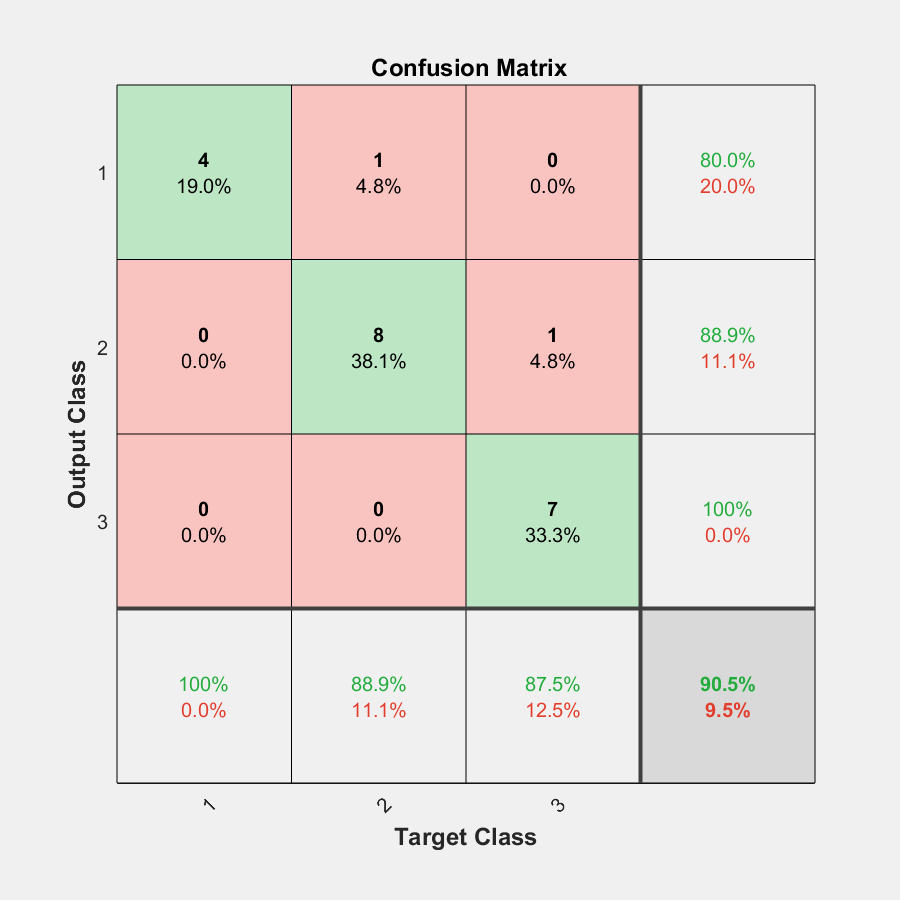

i = 5

cases = 25

performance = 0.1373

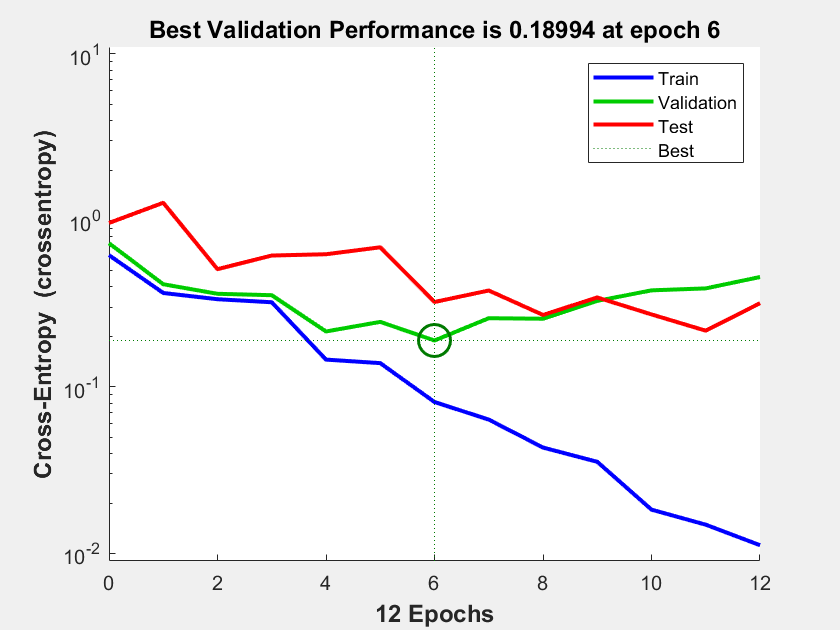

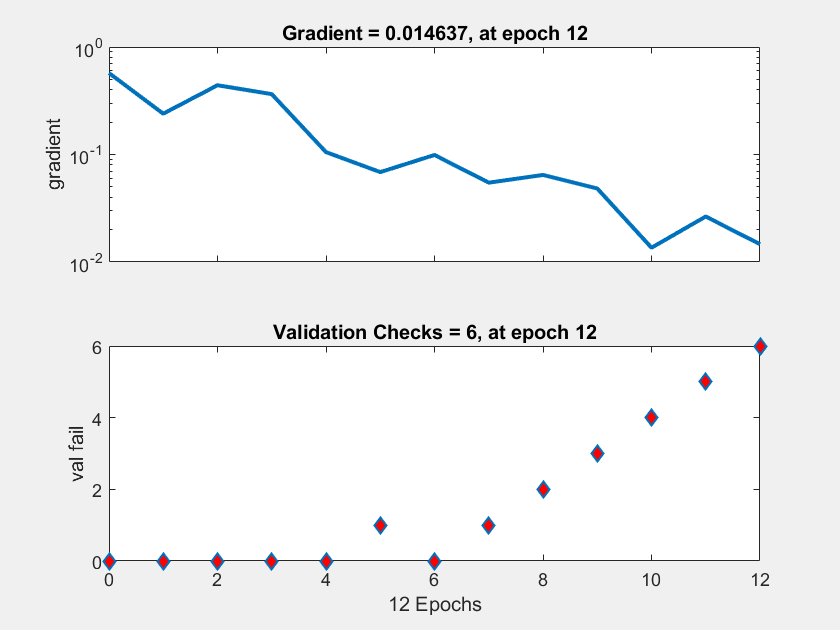

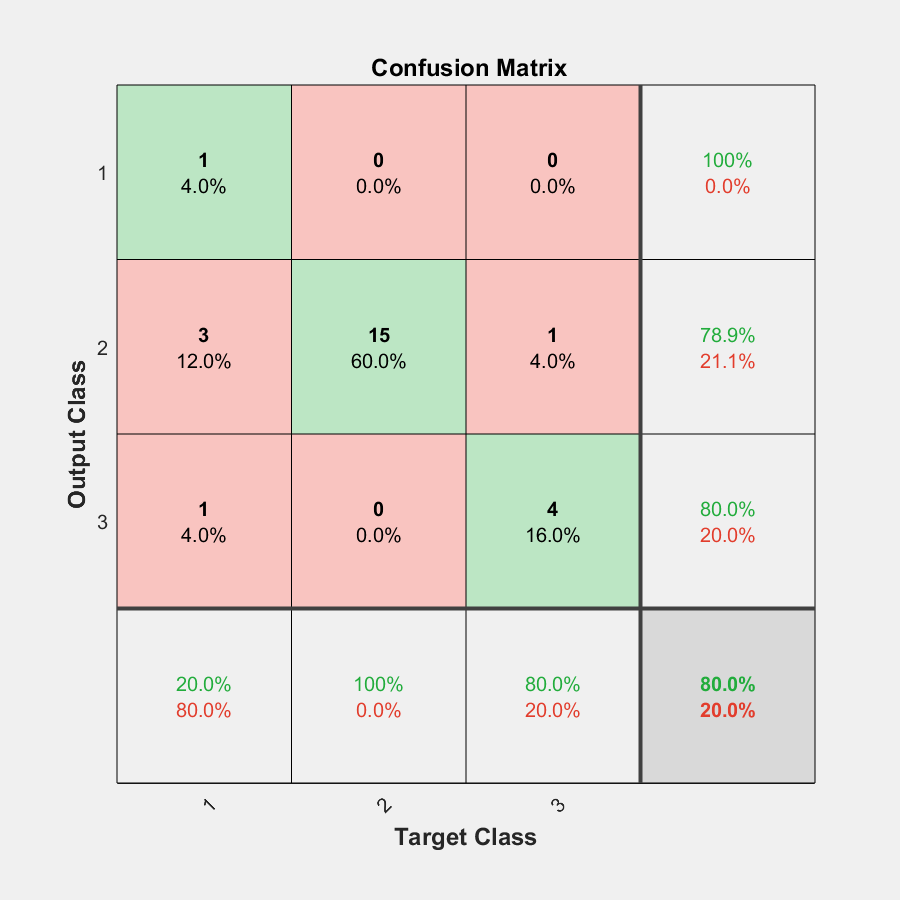

i = 6

cases = 23

performance = 1.3624e-07

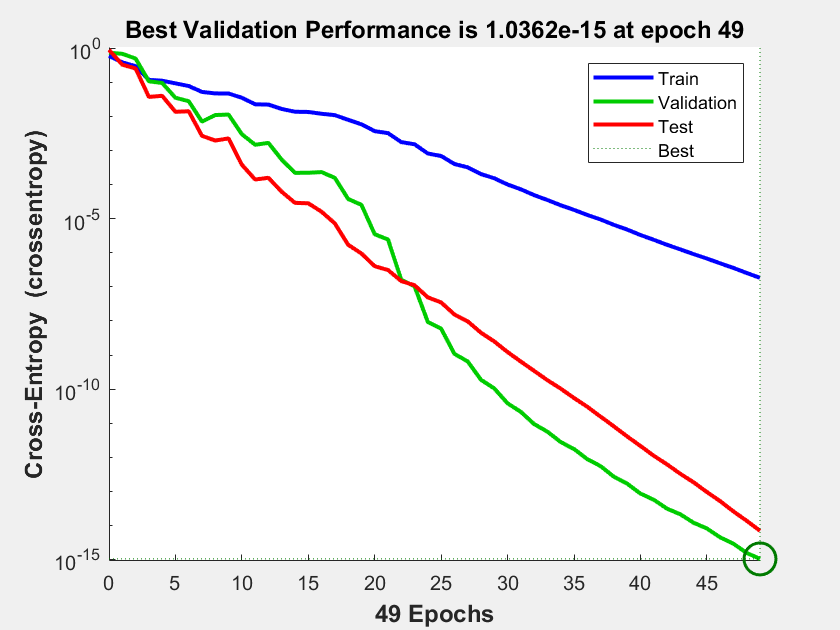

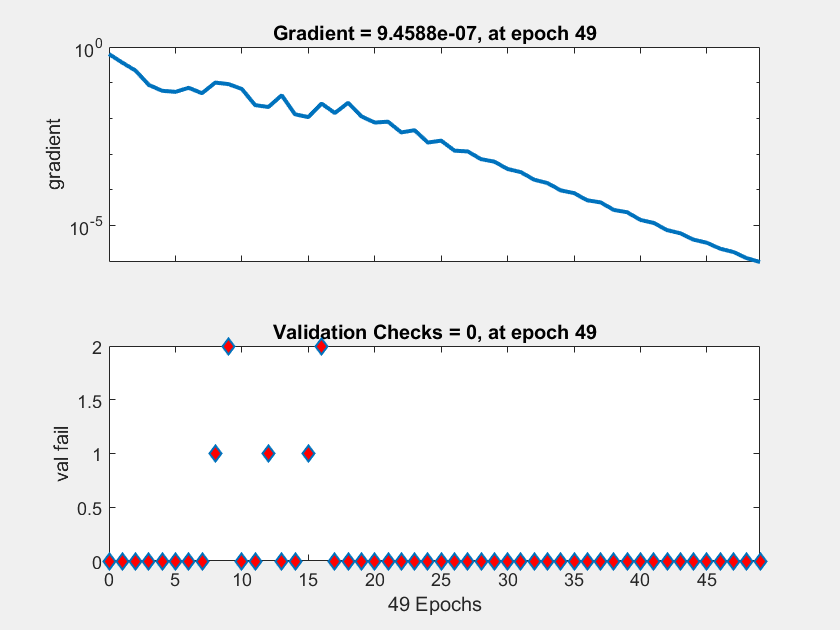

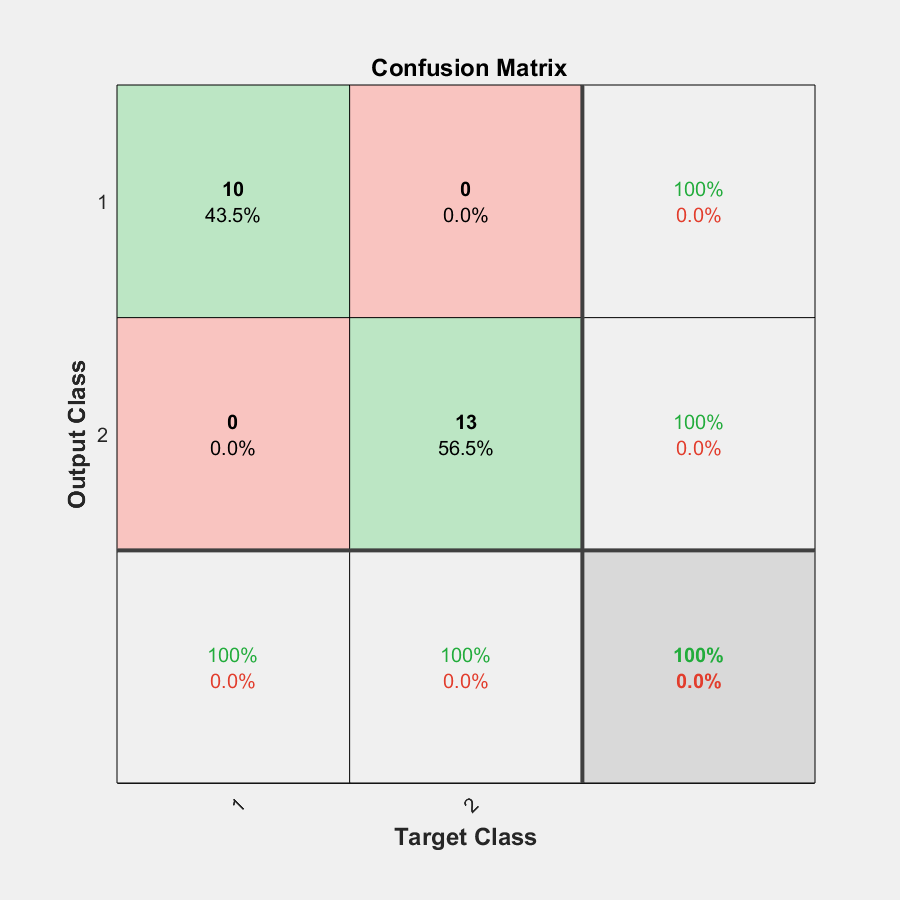

i = 7

cases = 11

performance = 2.2204e-16

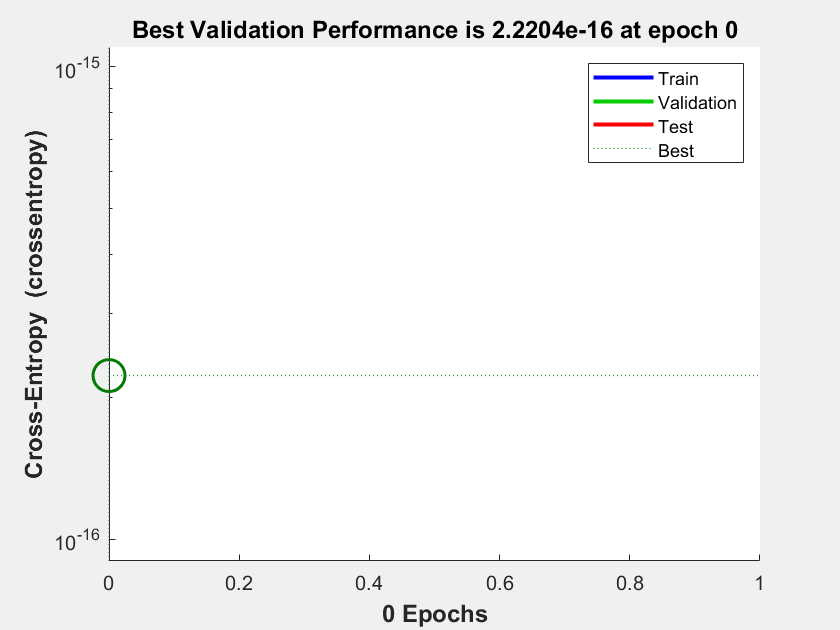

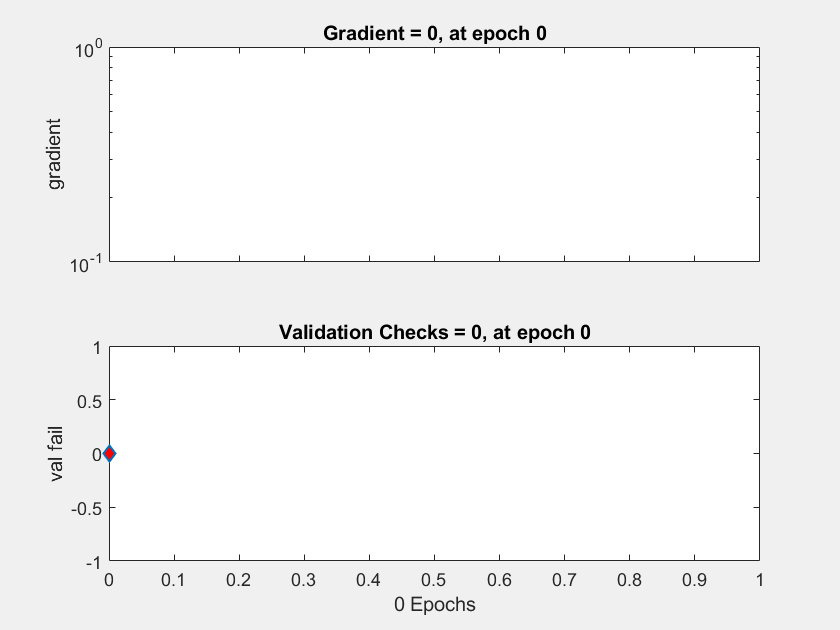

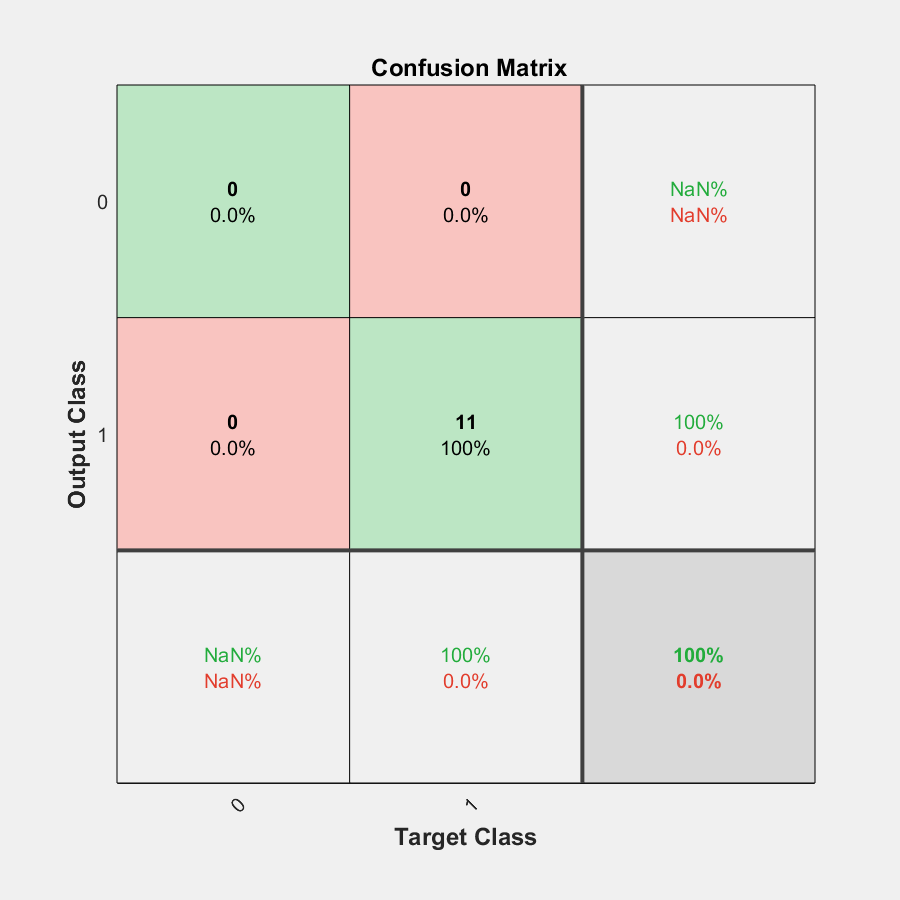

i = 8

cases = 16

performance = 0.1721

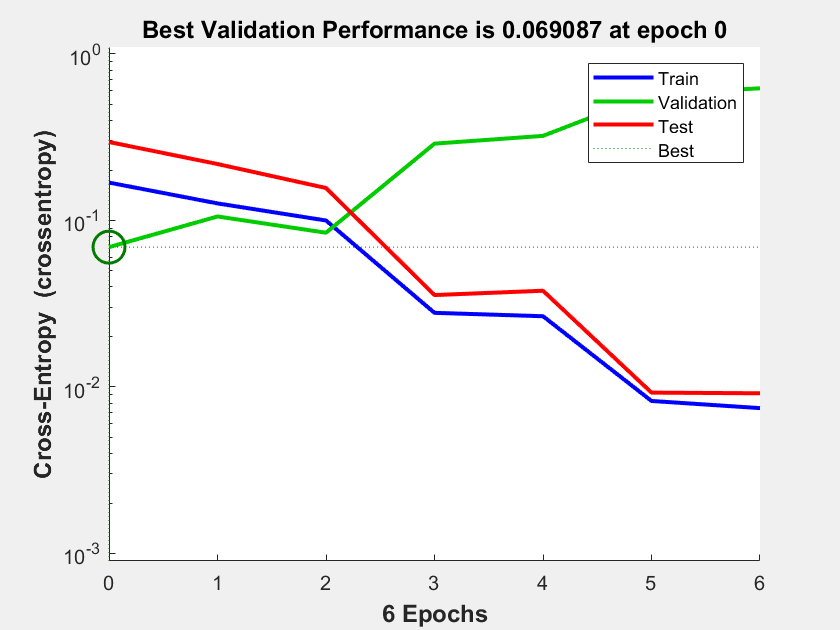

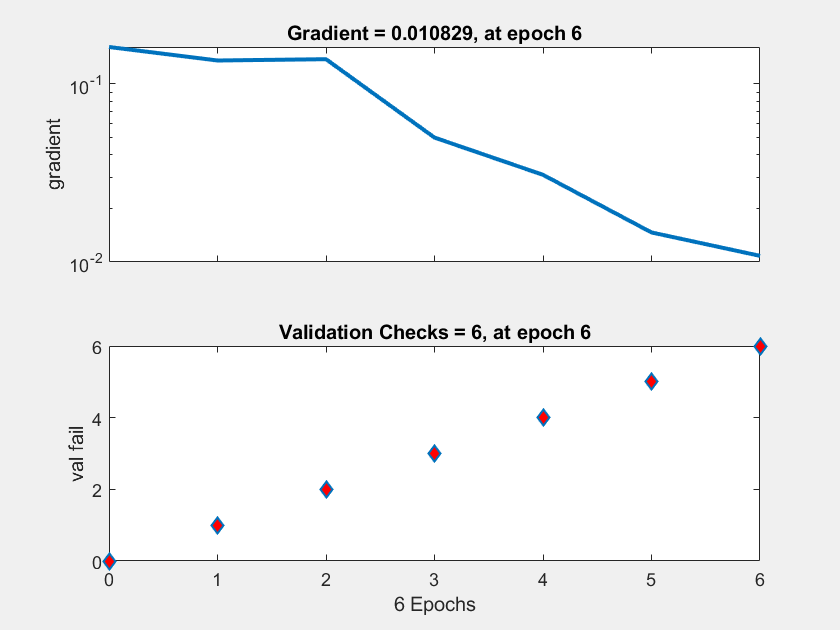

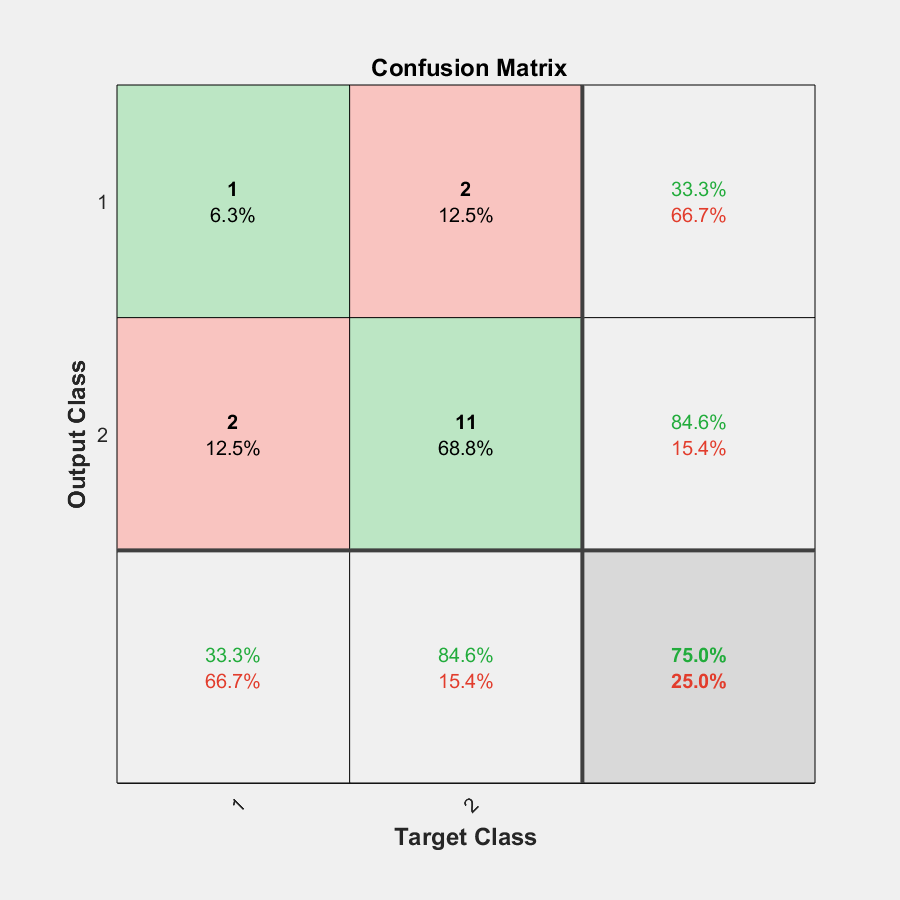

i = 9

cases = 30

performance = 1.6685e-04

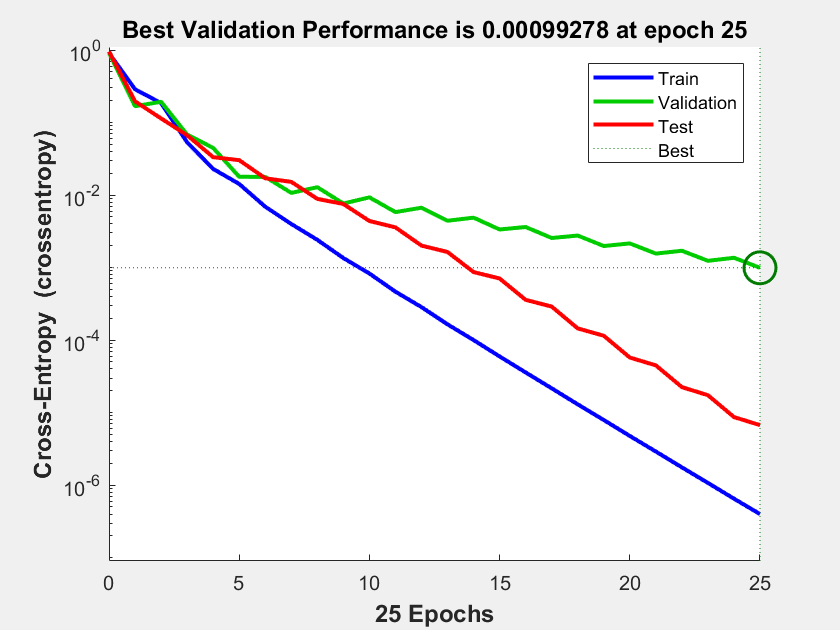

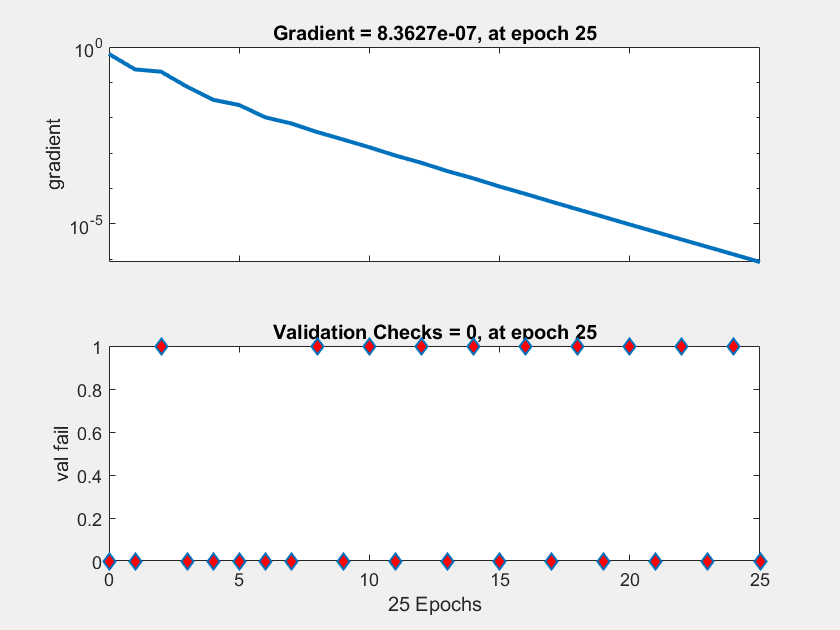

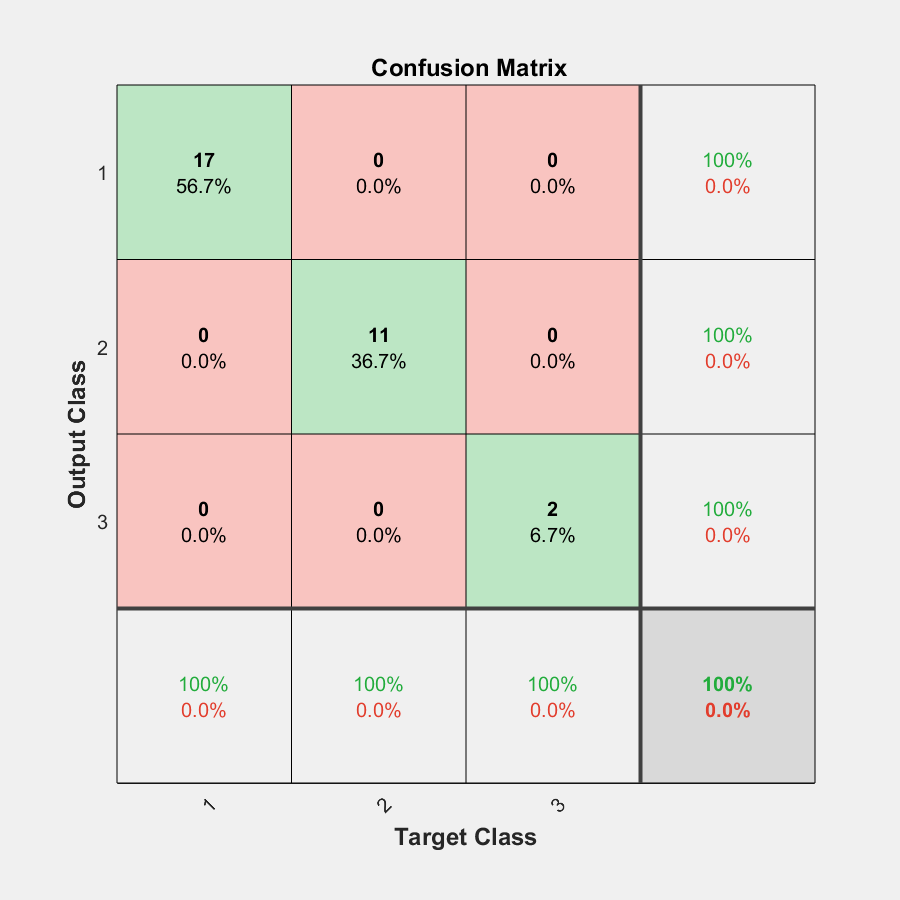

i = 10

cases = 7

performance = 2.6130e-07

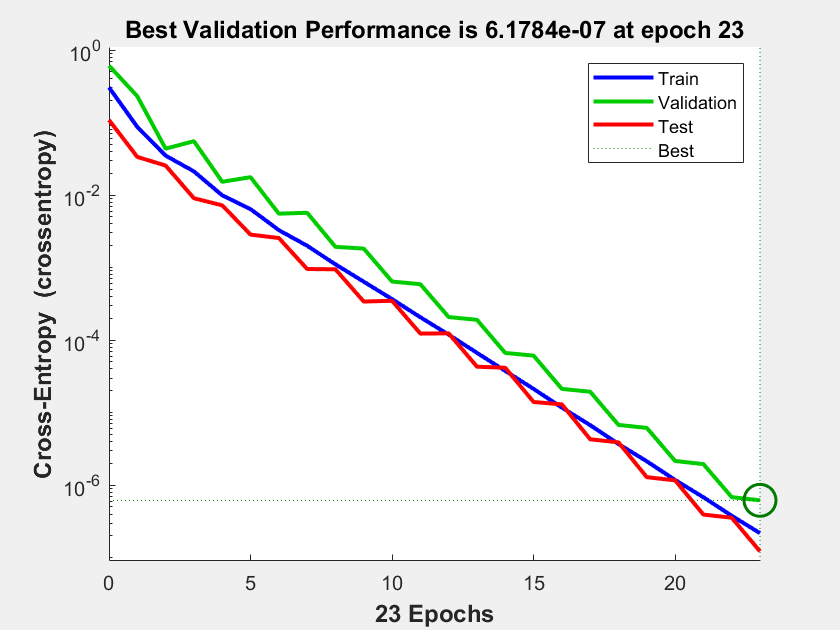

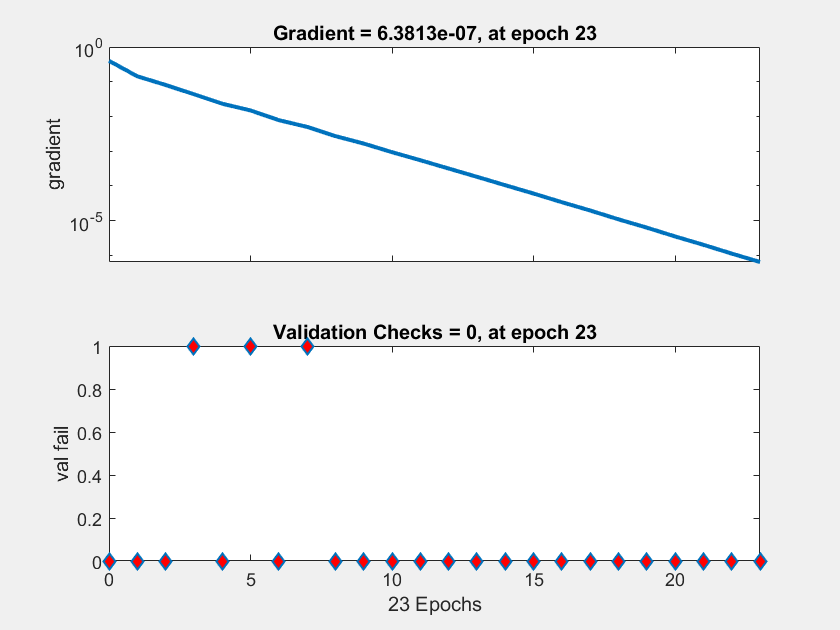

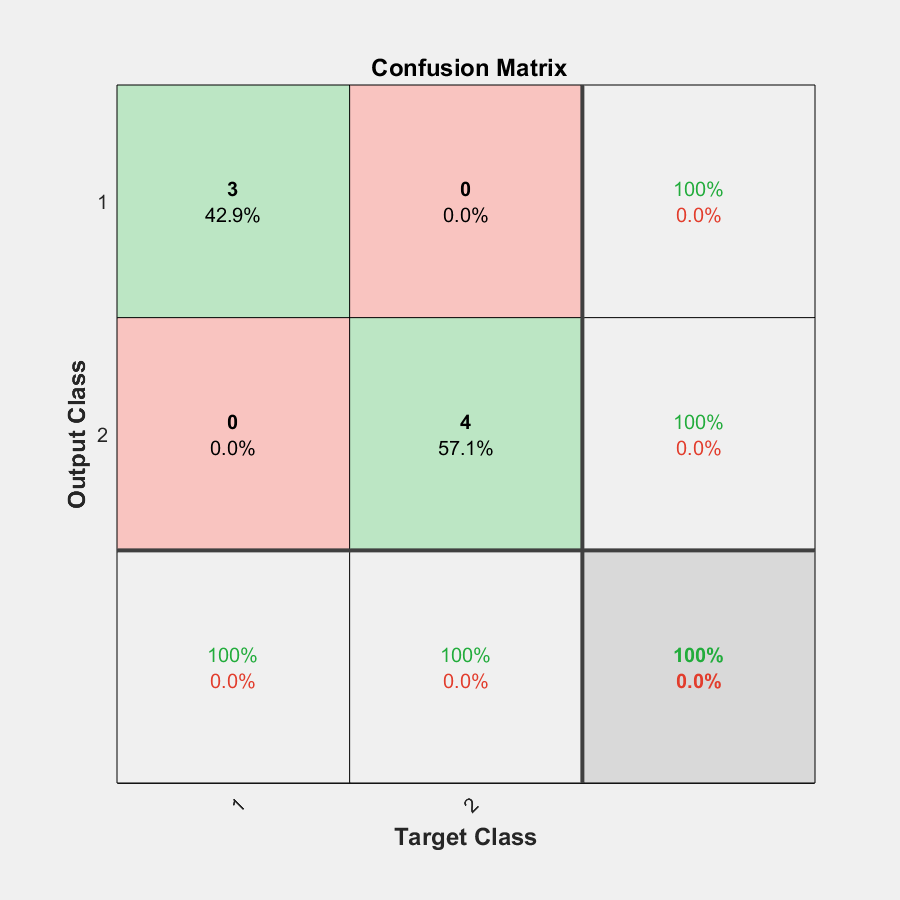

for i = 1:1:numOfTargets
    inputs = collectedInputMatrix{i};
    targets = collectedOutputMatrix{i};
    
    hiddenLayerSize = 10;
    net = patternnet(hiddenLayerSize);
    
    net.divideParam.trainRatio = 70/100;
    net.divideParam.valRatio = 15/100;
    net.divideParam.testRatio = 15/100;
    
    [net,tr] = train(net,inputs,targets);

    outputs = net(inputs);
%     errors = gsubtract(targets,outputs)
    i
    cases = sum(dataCountMatrix(i,:))
    performance = perform(net,targets,outputs)
    
    figure, plotperform(tr);
    figure, plottrainstate(tr);
    figure, plotconfusion(targets,outputs);
%     figure, ploterrhist(errors)
    
end

### Neural Network Demo

clc
clear all
close all

% Solve a Pattern Recognition Problem with a Neural Network
% Script generated by NPRTOOL
%
% This script assumes these variables are defined:
%
%   cancerInputs - input data.
%   cancerTargets - target data.

% No of rows  = dimension of the inputs (Num of features?)
% No of cols  = num of inputs (data points)
inputs  = [0 0 0 0 5 5 5 5; 0 0 5 5 0 0 5 5];

% No of rows = num of outputs we have
% No of cols  = num of inputs (data points)
targets = [1 0 0 0 0 0 0 0; 0 1 1 1 1 1 1 0; 0 0 0 0 0 0 0 1];

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize);


% Set up Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;


% Train the Network
[net,tr] = train(net,inputs,targets);

% Test the Network
outputs = net(inputs);
errors = gsubtract(targets,outputs);
performance = perform(net,targets,outputs)

% View the Network
view(net)

% Plots
% Uncomment these lines to enable various plots.
figure, plotperform(tr)
figure, plottrainstate(tr)
figure, plotconfusion(targets,outputs)
figure, ploterrhist(errors)